# Part(III) Modeling Tensile Stress-Strain Response of Mild Steel Reinforcement

This portion of the homework looks to model the behavior of steel rebar using different stiffness hardening models using results from a cyclic loading on a coupon test. The aspect ratio of the test coupon is sufficiently small to ensure that nonlinear geometrical effects are negligible. 

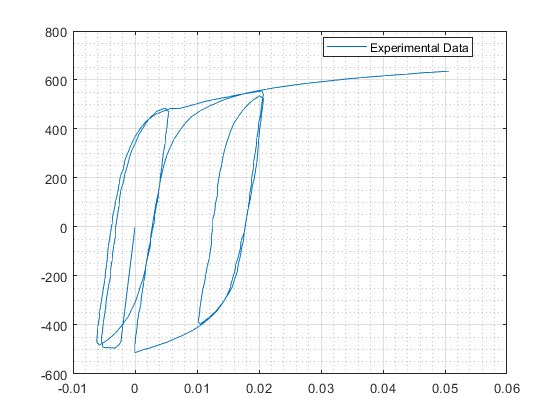

clear; clc; close all; hold on; grid on; box on; % Housekeeping
[test_stress, test_strain] = get_data_for_range(); % Get data from excel
plot_model(test_strain, test_stress,(1:273),"Experimental Data"); % Plot the test data

[fy, fsu, Es, esh, esu] = get_material_prop(); Es = Es*10^3; % Grabs the material property
ey = fy/Es; zeta = 0.6; r = (fsu/fy - 1) / (zeta*esu/ey - 1); % Calculates some properties

## Question 1. Kinematic Hardening Cyclic Model

Use a kinematic hardneing cyclic model for $\zeta =0\ldotp 6$ to predic the bar stress corresponding to each strain. The code was optimized a little in comparison with the Isotropic Hardening model as this model was developed second- also why it's lavel model2. 

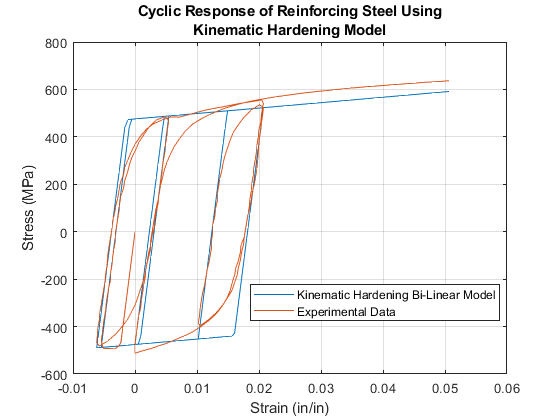

[model2_strain, model2_stress] = deal(zeros(numel(test_strain),1)); % Initialize model
strain_max = 0; stress_max = 0; % Initial max bounds 
strain_min = -ey; stress_min = -fy; % Initial min bounds 
branch = 3; % Initial branch
end_no = 273; % Last index of model (used for developing branch by branch)

for index = 2:end_no % For all of the strains in the test strains
    delta_strain = test_strain(index) - test_strain(index -1); % Find the change in strain
    model2_strain(index) = test_strain(index); % Take the current test strain (unnecessary actually)
    
    if branch == 1 || branch == 3 % If you're on branch 1 or 3
        if strain_min <= model2_strain(index) && model2_strain(index) <= strain_max % As long as you're within the bounds 
            model2_stress(index) = min(max(Es * (model2_strain(index)-strain_min) + stress_min,stress_min),stress_max); % Calculate the stress
        else % You're moving to a different branch 
            if model2_strain(index) > strain_max % If moving to the right, Moving from branch 1 -> 2
                branch = 2; % Set new branch 
                strain_min = strain_max; % Set new min
                stress_min = stress_max; % Set new min
            elseif model2_strain(index) < strain_min % If moving to the left,  Moving from Branch 3 -> 4
                branch = 4; % Set new branch
            end 
        end          
    end
    
    if (branch == 2 && delta_strain > 0) || (branch == 4 && delta_strain < 0) % On Branch 2 || 4, and the directions are correct
        model2_stress(index) = r*Es*(model2_strain(index) - strain_min) + stress_min; % Calculate the stress
    else % The direction has reversed and moving to a new branch 
        if delta_strain >= 0 && branch == 4 % If moving to the right, Moving from Branch 4 -> 1 
            branch = 1; % New Branch
            strain_min = model2_strain(index -1); stress_min = model2_stress(index-1); % Set the min as the previous dot
            stress_max = stress_min + (2*fy); strain_max = strain_min + 2*ey; % The yield point is 2*fy and 2*ey away
            model2_stress(index) = Es * (model2_strain(index)-strain_min) + stress_min; % Should be capped at stress min     
        elseif delta_strain < 0 && branch == 2 % If moving to the left, Moving from Branch 2 -> 3 
            branch = 3; % New Branch
            strain_max = model2_strain(index -1 ); stress_max = model2_stress(index-1); % Set the min as the previous dot
            stress_min = model2_stress(index-1) - (2*fy); strain_min = strain_max - 2*ey; % The yield point is 2*fy and 2*ey away
            model2_stress(index) = Es * (model2_strain(index)-strain_min) + stress_min; % Should be capped at stress max 
        end
    end
end

close all; range = 1:end_no;
plot_model(model2_strain,model2_stress,range,"Kinematic Hardening Bi-Linear Model"); 
plot_model(test_strain, test_stress,range,"Experimental Data"); 
title(["Cyclic Response of Reinforcing Steel Using","Kinematic Hardening Model"])
legend("Location","best"); ylabel("Stress (MPa)"); xlabel("Strain (in/in)"); %
print_figure(13)

## Question 2. Isotropic Hardening Cyclic Model

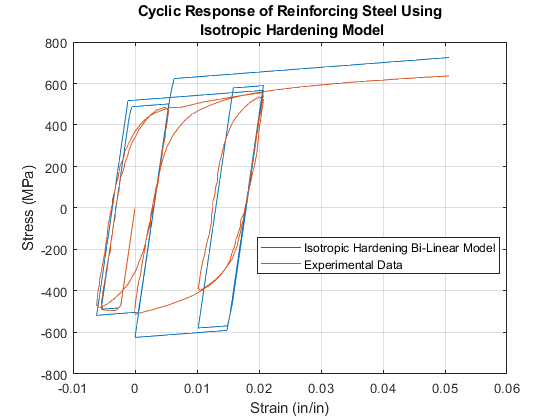

[model1_strain, model1_stress] = deal(zeros(numel(test_strain),1)); % Initialize model
strain_max = 0; stress_max = 0; % Initial max bounds 
strain_min = -ey; stress_min = -fy; % Initial min bounds 
branch = 3; % Initial branch
end_no = 273; % Last index of model (used for developing branch by branch)

for index = 2:end_no % For all of the strains in the test strains
    delta_strain = test_strain(index) - test_strain(index -1); % Find the change in strain
    model1_strain(index) = test_strain(index); % Take the current model strain
    
    if branch == 1 || branch == 3 % If you're on branch 1 or 3
        if strain_min <= model1_strain(index) && model1_strain(index) <= strain_max % As long as you're within the bounds 
            model1_stress(index) = Es * (model1_strain(index)-strain_max) + stress_max; % Calculate the stress
        else % You're moving to a different branch 
            if model1_strain(index) > strain_max % If moving to the right, Moving from branch 1 -> 2
                branch = 2; % Set new branch 
                model1_stress(index) = min(r*Es * (model1_strain(index)-strain_max) + stress_max, stress_max); % Use branch 2's eq
                [strain_min, stress_min] = deal(model1_strain(index) , model1_stress(index)); % Set new min
            elseif model1_strain(index) < strain_min % If moving to the left,  Moving from Branch 3 -> 4
                branch = 4; % Set new branch
                model1_stress(index) = r*Es * (model1_strain(index)-strain_min) + stress_min; % Use branch 4's eq
                [strain_max, stress_max] = deal(model1_strain(index) , model1_stress(index)); % Set new max
            end 
        end          
    end
    
    if (branch == 2 && delta_strain > 0) || (branch == 4 && delta_strain < 0) % On Branch 2 || 4, and the directions are correct
        model1_stress(index) = r*Es*(model1_strain(index) - strain_min) + stress_min; % Calculate the stress
    else % The direction has reversed and moving to a new branch 
        if delta_strain >= 0 && branch == 4 % If moving to the right, Moving from Branch 4 -> 1 
            branch = 1; % New Branch
            strain_min = model1_strain(index -1 ); stress_min = model1_stress(index-1); % Set the min as the previous dot
            stress_max = -model1_stress(index-1); strain_max = strain_min + abs(2*model1_stress(index-1)/Es); % yield point is equal distance away
            model1_stress(index) = max(Es * (model1_strain(index) - strain_min) + stress_min, stress_min); % Use branch 1's eq      
        elseif delta_strain < 0 && branch == 2 % If moving to the left, Moving from Branch 2 -> 3 
            branch = 3; % New Branch
            strain_max = model1_strain(index -1 ); stress_max = model1_stress(index-1);% Set the min as the previous dot
            stress_min = -model1_stress(index-1); strain_min = strain_max - abs(2*model1_stress(index-1)/Es); % yield point is equal distance away
            model1_stress(index) = min(Es * (model1_strain(index) - strain_max) + stress_max, stress_max); % Use branch 3's eq 
        end
    end
end

close all; range = 1:end_no;
plot_model(model1_strain,model1_stress,range,"Isotropic Hardening Bi-Linear Model"); plot_model(test_strain, test_stress,range,"Experimental Data"); 
title(["Cyclic Response of Reinforcing Steel Using"," Isotropic Hardening Model"])
legend("Location","best"); ylabel("Stress (MPa)"); xlabel("Strain (in/in)"); %
print_figure(14)

## Question 3. Combined Kinematic-Isotropic Hardening Cyclic Model

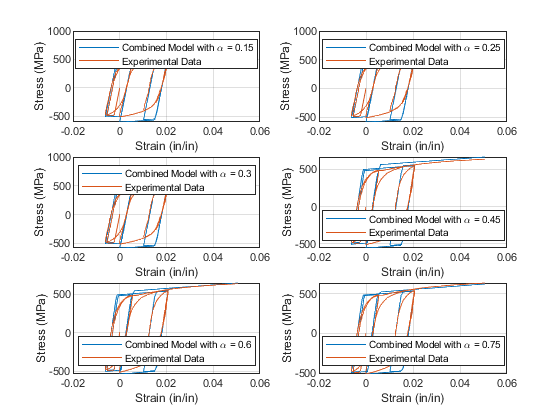

alpha_values = [0.15, 0.25, 0.3, 0.45, 0.6, 0.75]; % As specified 
figure % One figure with 6 subplots
i = 1; % Counter for plot number
for a = alpha_values
    subplot(3,2,i); i = i+1; % Subplot i-th
    stress = (1-a)*model1_stress + a*model2_stress; % Calculate the combined stress values
    plot_model(model2_strain,stress,range,"Combined Model with \alpha = " + string(a)); % Plots combined stress
    plot_model(test_strain, test_stress,range,"Experimental Data"); % Adds the experimental data
    legend("Location","best"); ylabel("Stress (MPa)"); xlabel("Strain (in/in)"); %
end
print_figure('14a')

Find the best alpha value.

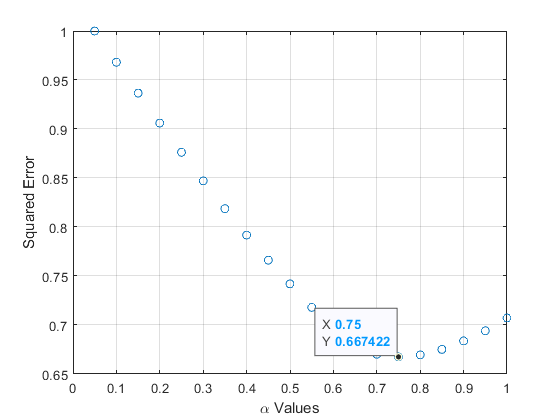

figure() % new figure
alpha_values = linspace(0.05,1,20); % Test values for alpha
sq_error = zeros(length(alpha_values),1); % Sq errors
i = 1; % Double loop counter 
for a = alpha_values % For various alpha values
    stress = (1-a)*model1_stress + a*model2_stress; % Calculate the all of the stresses
    sq_error(i) = sum(sqrt((stress - test_stress).^2)); i = i+1; % Calculate the sq error
end
sq_error = sq_error/ max(sq_error);
plt = scatter(alpha_values,sq_error); % Plot
datatip(plt,'DataIndex',find(sq_error==min(sq_error)),"Location","northwest"); %Label Minimum
xlabel("\alpha Values",'Interpreter','tex'); ylabel("Squared Error"); box on, grid on; % options
print_figure('14b') % Save as pdf

function plt = plot_model(strain,stress,range,name)
    plt = plot(strain(range),stress(range),"DisplayName",name); 
    hold on; legend("location","best"); grid minor; grid on;
end


function [stress, strain] = get_data_for_range()
    opts = spreadsheetImportOptions("NumVariables", 3);
    
    % Specify sheet and range
    opts.Sheet = "Data 2021";
    opts.DataRange = "A14:C286";
    
    % Specify column names and types
    opts.VariableNames = ["Strain","Stress","Blank"];
    opts.VariableTypes = ["double", "double", "double"];
    
    % Import the data
    tbl = readtable("C:\Users\Louis Lin\Workspace\Academic\UCSD\SE 211\Homework\HW 1\data\Machined coupon cyclic test 2021.xlsx", opts, "UseExcel", false);
 
    stress = tbl.Stress; 
    strain = tbl.Strain;
end

function [fy, fsu, Es, esh, esu] = get_material_prop()
    opts = spreadsheetImportOptions("NumVariables", 1);
    opts.Sheet = "Data 2021";
    opts.DataRange = "B4:B8";
    opts.VariableNames = "info";
    opts.VariableTypes = "double";
    tbl = readtable("C:\Users\Louis Lin\Workspace\Academic\UCSD\SE 211\Homework\HW 1\data\Machined coupon cyclic test 2021.xlsx", opts, "UseExcel", false);
    info = num2cell(tbl.info);
    [fy, fsu, Es, esh, esu] = deal(info{:});
end

function print_figure(no)
    orient(gcf,'landscape');
    folder = '..\figures\';
    name = 'Figure' +string(no);
    print(folder+name,'-dpdf','-PMicrosoft Print to PDF','-fillpage','-r600','-painters')
end